# Hard Sphere Gas

We want to simulate in a Monte Carlo simulation an hard sphere gas in a cosolute using the A-O model 

L=3;
r=0.1;
R=1;

R_1=rand(1,3)*L;
while 1
    R_2=rand(1,3)*L;
    if (norm(R_1-R_2-L*round((R_1-R_2)/L))>2*R)
        break
    end
end

N=10;
r_c=[];
for i = 1:N
    while 1
        r_p=rand(1,3)*L;
        if ((norm(r_p-R_2-L*round((r_p-R_2)/L))>R+r) && (norm(r_p-R_1-L*round((r_p-R_1)/L))>R+r))
            break
        end
    end
    r_c=[r_c;r_p];
end
r_c

r_c =     1.5446    1.4215    0.6216
    0.8541    1.3027    2.9806
    0.0789    0.2027    2.9413
    1.1443    1.7517    2.2808
    1.6541    1.8877    0.2206
    0.3281    2.9248    0.8738
    1.2442    0.9875    0.4649
    0.5748    2.9537    0.4956
    2.2436    1.5132    1.3821
    1.8500    2.4252    0.6874


[x,y,z]=sphere;

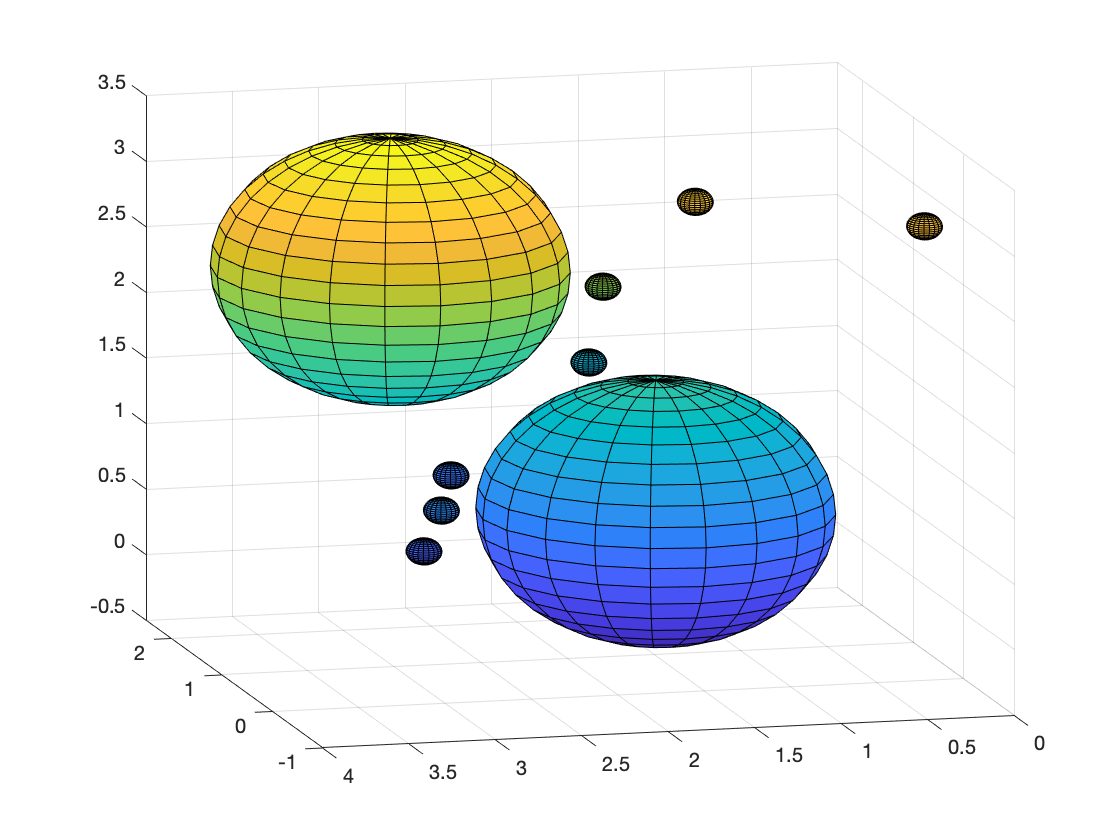

clf
plot3(r_c(:,1),r_c(:,2),r_c(:,3),'b.')
hold on
plot3(R_1(:,1),R_1(:,2),R_1(:,3),R_2(:,1),R_2(:,2),R_2(:,3),'r.')
surf(x*R+R_1(:,1),y*R+R_1(:,2),z*R+R_1(:,3))
surf(x*R+R_2(:,1),y*R+R_2(:,2),z*R+R_2(:,3))
for i =1:N
   surf(x*r+r_c(i,1),y*r+r_c(i,2),z*r+r_c(i,3)) 
end
grid on
hold off

clf
for t= 1:1000 
    for i = 1:N+1
        r_p=rand(1,3);
        r_p=r_p/norm(r_p)*r/10;
        n_p=randi(N+1);
        if n_p==N+1
            R_p=R_2+r_p;
            if ((norm(R_p-R_1-L*round((R_p-R_1)/L))>2*R) && ...
                    all(vecnorm(R_p-r_c-L*round((R_p-r_c)/L),2,2)>R+r))
                R_2=R_p-L*round(R_p/L);
            end
        else
            R_p=r_p+r_c(n_p,:);
            if (norm(R_p-R_1-L*round((R_p-R_1)/L))>r+R) && ...
                    (norm(R_p-R_2-L*round((R_p-R_2)/L))>r+R)
                r_c(n_p,:)=R_p-L*round(r_c(n_p,:)/L);
            end
        end
    end
end

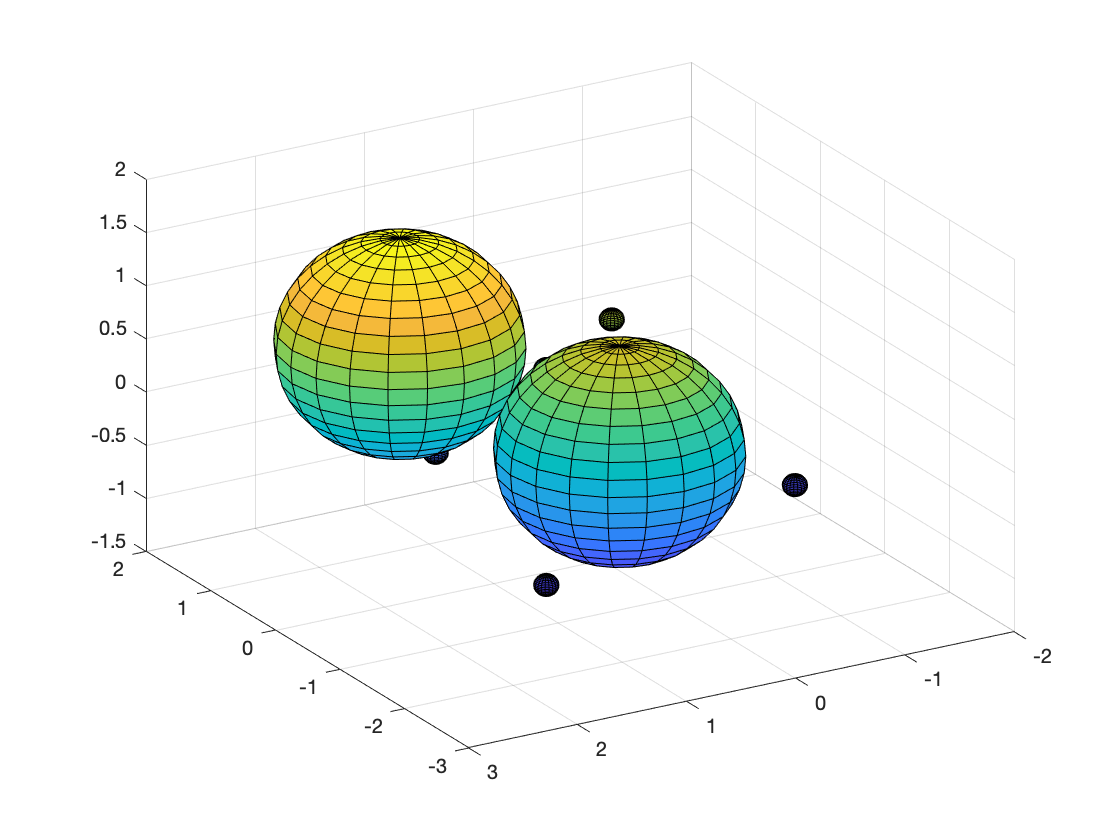


clf
plot3(r_c(:,1),r_c(:,2),r_c(:,3),'b.')
hold on
plot3(R_1(:,1),R_1(:,2),R_1(:,3),R_2(:,1),R_2(:,2),R_2(:,3),'r.')
surf(x*R+R_1(:,1),y*R+R_1(:,2),z*R+R_1(:,3))
surf(x*R+R_2(:,1),y*R+R_2(:,2),z*R+R_2(:,3))
for i =1:N
   surf(x*r+r_c(i,1),y*r+r_c(i,2),z*r+r_c(i,3)) 
end
grid on
hold off